clear all; close all;
A = -100.34; 
B = 7.367; 
C = -4.92;
D = 9.111;
E = -99.99;
F = 134.56;
Y_double = (A+B)*C + (D+E)*(E+F);

sign=1;
% Najważniejsze obliczenia
A_fix = fi(A,sign,18,8);
B_fix = fi(B,sign,8,3);
C_fix = fi(C,sign,12,7);
D_fix = fi(D,sign,8,2);
E_fix = fi(E, sign, 14, 5);
F_fix = fi(F, sign, 19, 9);
sum_AB = A_fix + B_fix

sum_AB =   -92.9648

          DataTypeMode: Fixed-point: binary point scaling
            Signedness: Signed
            WordLength: 19
        FractionLength: 8

mult_AB_C = sum_AB * C_fix

mult_AB_C =   457.5613

          DataTypeMode: Fixed-point: binary point scaling
            Signedness: Signed
            WordLength: 31
        FractionLength: 15

sum_DE = D_fix + E_fix

sum_DE =    -91

          DataTypeMode: Fixed-point: binary point scaling
            Signedness: Signed
            WordLength: 15
        FractionLength: 5

sum_EF = E_fix + F_fix

sum_EF =    34.5605

          DataTypeMode: Fixed-point: binary point scaling
            Signedness: Signed
            WordLength: 20
        FractionLength: 9

mult_DE_EF = sum_DE * sum_EF

mult_DE_EF =   -3.1450e+03

          DataTypeMode: Fixed-point: binary point scaling
            Signedness: Signed
            WordLength: 35
        FractionLength: 14

Y_fix = mult_AB_C + mult_DE_EF

Y_fix =   -2.6874e+03

          DataTypeMode: Fixed-point: binary point scaling
            Signedness: Signed
            WordLength: 37
        FractionLength: 15

Y_vivado = -2687.44842529297;
diff = Y_vivado - Y_fix

diff =      0

          DataTypeMode: Fixed-point: binary point scaling
            Signedness: Signed
            WordLength: 38
        FractionLength: 15


error=abs(Y_double-Y_vivado)

error = 3.1886


sign=1; %0-unsigned value, 1-signed value % sign
prec_i=1; %number of integer part bits (Nc) % one bit
prec_f=10; %number of fractional part bits (Nu) % ten bits
word = sign + prec_i + prec_f; % whole word

A_fix = fi(A,sign,18,8);
B_fix = fi(B,sign,8,3);
C_fix = fi(C,sign,12,7);
D_fix = fi(D,sign,8,2);
E_fix = fi(E, sign, 14, 5);
F_fix = fi(F, sign, 19, 9);
A_fix + B_fix

ans =   -92.9648

          DataTypeMode: Fixed-point: binary point scaling
            Signedness: Signed
            WordLength: 19
        FractionLength: 8



A_double = double(A_fix);
B_double = double(B_fix);
C_double = double(C_fix);

sum_fix = (A_fix+B_fix);
Y_fix = sum_fix*C_fix;
Y_double = double(Y_fix)

Y_double = 457.5613


Y = (A+B);
Y = Y * C

Y = 457.4272


difference = abs(Y-Y_double)

difference = 0.1342

bin(A_fix)

ans = '111001101110101001'

bin(B_fix)

ans = '00111011'

bin(C_fix)

ans = '110110001010'

bin(D_fix)

ans = '00100100'

bin(E_fix)

ans = '11001110000000'

bin(F_fix)

ans = '0010000110100011111'


bin(sum_fix)

ans = '1111010001100001001'

Y_fix

Y_fix =   457.5613

          DataTypeMode: Fixed-point: binary point scaling
            Signedness: Signed
            WordLength: 31
        FractionLength: 15

bin(Y_fix)

ans = '0000000111001001100011111011010'




Y_all_fix = ((A_fix+B_fix) * C_fix) + ((D_fix+E_fix) * (E_fix + F_fix))

Y_all_fix =   -2.6874e+03

          DataTypeMode: Fixed-point: binary point scaling
            Signedness: Signed
            WordLength: 37
        FractionLength: 15

A = bin2fixed('000101001011', 1, 1, 10)

A = 0.3232

B = bin2fixed('110011011010', 1, 1, 10)

B = -0.7871

C = bin2fixed('001001000011', 1, 1, 10)

C = 0.5654


A_sum_B = A + B

A_sum_B = -0.4639

A_sum_B_vivado = bin2fixed('1111000100101', 1, 2, 10)

A_sum_B_vivado = -0.4639


AB_mult_C = A_sum_B * C

AB_mult_C = -0.2623


Mult_vivado = bin2fixed('1111110111100110110101111', 1, 4, 20)

Mult_vivado = -0.2623


diff = AB_mult_C - Mult_vivado

diff = 0

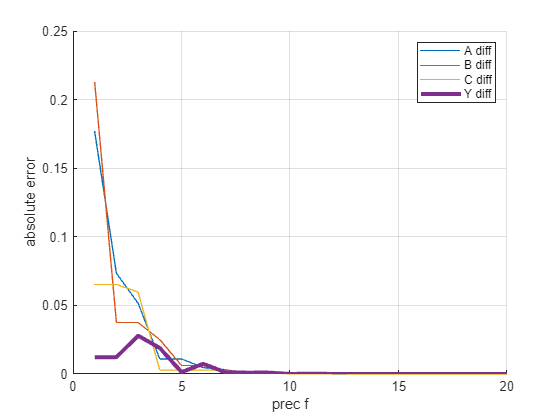

clear all; close all;
A = 0.32345; B = -0.78743; C = 0.56532;
Y = (A+B)*C;
prec_f = 1:20; %SET!!!
diff_A = []; diff_B = []; diff_C = []; diff_Y = [];
size_pf = size(prec_f);
for i=1:size_pf(2)
    A_fix = fi(A,1,prec_f(i)+2,prec_f(i));
    B_fix = fi(B,1,prec_f(i)+2,prec_f(i));
    C_fix = fi(C,1,prec_f(i)+2,prec_f(i));
    Y_fix = (A_fix+B_fix)*C_fix;
    diff_A(end+1)=abs(A-double(A_fix));
    diff_B(end+1)=abs(B-double(B_fix));
    diff_C(end+1)=abs(C-double(C_fix));
    diff_Y(end+1)=abs(Y-double(Y_fix));
end
figure
hold on
plot(prec_f,diff_A,'DisplayName','A diff')
plot(prec_f,diff_B,'DisplayName','B diff')
plot(prec_f,diff_C,'DisplayName','C diff')
plot(prec_f,diff_Y,'DisplayName','Y diff','LineWidth',3)
xlabel('prec f'), ylabel('absolute error')
legend(), grid(), hold off

% wybieram pracyzję 10 po przecinku


% Pozostałe przypadki testowe

% Losowe liczby dla A, B, C, D, E, F 1
A = 7.53;
B = -3.14;
C = 5.78;
D = -6.25;
E = 2.99;
F = -8.75;
Y_double = (A+B)*C + (D+E)*(E+F)

Y_double = 44.1518

% Konwersja na stałoprzecinkowe
A_fix = fi(A, 1, 18, 8);
B_fix = fi(B, 1, 8, 3);
C_fix = fi(C, 1, 12, 7);
D_fix = fi(D, 1, 8, 2);
E_fix = fi(E, 1, 14, 5);
F_fix = fi(F, 1, 19, 9);

% Wyświetlanie wartości binarnych
bin_A = bin(A_fix)

bin_A = '000000011110001000'

bin_B = bin(B_fix)

bin_B = '11100111'

bin_C = bin(C_fix)

bin_C = '001011100100'

bin_D = bin(D_fix)

bin_D = '11100111'

bin_E = bin(E_fix)

bin_E = '00000001100000'

bin_F = bin(F_fix)

bin_F = '1111110111010000000'


Y_all_fix = ((A_fix+B_fix) * C_fix) + ((D_fix+E_fix) * (E_fix + F_fix))

Y_all_fix =    44.1611

          DataTypeMode: Fixed-point: binary point scaling
            Signedness: Signed
            WordLength: 37
        FractionLength: 15

Y_vivado = 44.1611328125;
diff_1 = Y_vivado - Y_all_fix

diff_1 =      0

          DataTypeMode: Fixed-point: binary point scaling
            Signedness: Signed
            WordLength: 38
        FractionLength: 15

% Losowe liczby dla A, B, C, D, E, F 2
A = 4.92;
B = -1.47;
C = 6.35;
D = -3.89;
E = 8.12;
F = -2.65;
Y_double = (A+B)*C + (D+E)*(E+F)

Y_double = 45.0456

% Konwersja na stałoprzecinkowe
A_fix = fi(A, 1, 18, 8);
B_fix = fi(B, 1, 8, 3);
C_fix = fi(C, 1, 12, 7);
D_fix = fi(D, 1, 8, 2);
E_fix = fi(E, 1, 14, 5);
F_fix = fi(F, 1, 19, 9);

% Wyświetlanie wartości binarnych
bin_A = bin(A_fix)

bin_A = '000000010011101100'

bin_B = bin(B_fix)

bin_B = '11110100'

bin_C = bin(C_fix)

bin_C = '001100101101'

bin_D = bin(D_fix)

bin_D = '11110000'

bin_E = bin(E_fix)

bin_E = '00000100000100'

bin_F = bin(F_fix)

bin_F = '1111111101010110011'


Y_all_fix = ((A_fix+B_fix) * C_fix) + ((D_fix+E_fix) * (E_fix + F_fix))

Y_all_fix =    44.3170

          DataTypeMode: Fixed-point: binary point scaling
            Signedness: Signed
            WordLength: 37
        FractionLength: 15

Y_vivado = 44.3170166015625;
diff_2 = Y_vivado - Y_all_fix

diff_2 =      0

          DataTypeMode: Fixed-point: binary point scaling
            Signedness: Signed
            WordLength: 38
        FractionLength: 15

% Losowe liczby dla A, B, C, D, E, F 3
A = 3.47;
B = -5.86;
C = 2.19;
D = -4.01;
E = 7.64;
F = -9.28;
Y_double = (A+B)*C + (D+E)*(E+F)

Y_double = -11.1873

% Konwersja na stałoprzecinkowe
A_fix = fi(A, 1, 18, 8);
B_fix = fi(B, 1, 8, 3);
C_fix = fi(C, 1, 12, 7);
D_fix = fi(D, 1, 8, 2);
E_fix = fi(E, 1, 14, 5);
F_fix = fi(F, 1, 19, 9);

% Wyświetlanie wartości binarnych
bin_A = bin(A_fix)

bin_A = '000000001101111000'

bin_B = bin(B_fix)

bin_B = '11010001'

bin_C = bin(C_fix)

bin_C = '000100011000'

bin_D = bin(D_fix)

bin_D = '11110000'

bin_E = bin(E_fix)

bin_E = '00000011110100'

bin_F = bin(F_fix)

bin_F = '1111110110101110001'


Y_all_fix = ((A_fix+B_fix) * C_fix) + ((D_fix+E_fix) * (E_fix + F_fix))

Y_all_fix =   -11.2605

          DataTypeMode: Fixed-point: binary point scaling
            Signedness: Signed
            WordLength: 37
        FractionLength: 15

Y_vivado = -11.260498046875;
diff_3 = Y_vivado - Y_all_fix

diff_3 =      0

          DataTypeMode: Fixed-point: binary point scaling
            Signedness: Signed
            WordLength: 38
        FractionLength: 15

function value = bin2fixed(bin_str, sign, prec_i, prec_f)
    word = sign + prec_i + prec_f; % Obliczenie długości słowa

    % Konwersja binarnego stringa na liczbę dziesiętną
    int_value = bin2dec(bin_str);
    
    % Jeśli liczba jest podpisana (signed), sprawdzamy znak
    if sign == 1 && bin_str(1) == '1'
        % Ujemne liczby w notacji znak-moduł (two's complement)
        int_value = int_value - 2^word;
    end
    
    % Obliczenie wartości fixed-point
    value = int_value / 2^prec_f;
end